clc; clear all; close all;

rho = 850; % kg/m^3
beta = 900*10^6; % N/m^2

beta =    900000000


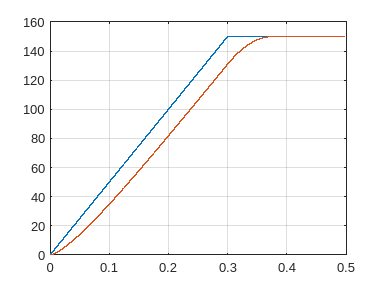


Cd = 0.55;
Ad = 3/10^6; % m^2

V2 = 2000/10^6; % m^3
p2 = 0; % bar
p1_max = 150*10^5; % Pa

t_r = 0.3; % s

simTime = 0.5; % s
t = 0;
dt = 10^-5; % s
idx = 1;

while(t <= simTime)
    % Calculations
    
    if(t <= t_r)
        p1 = t/t_r * p1_max;
    else
        p1 = p1_max;
    end
    Q = Cd * Ad * sign(p1-p2) * sqrt(2/rho*abs(p1-p2));
    p2Dot = beta/V2 * Q;

    % Logging
    tplt(idx) = t;
    p1plt(idx) = p1/10^5;
    p2plt(idx) = p2/10^5;

    % Time integration
    p2 = p2 + p2Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(tplt, p1plt)
hold on
plot(tplt,p2plt)
grid